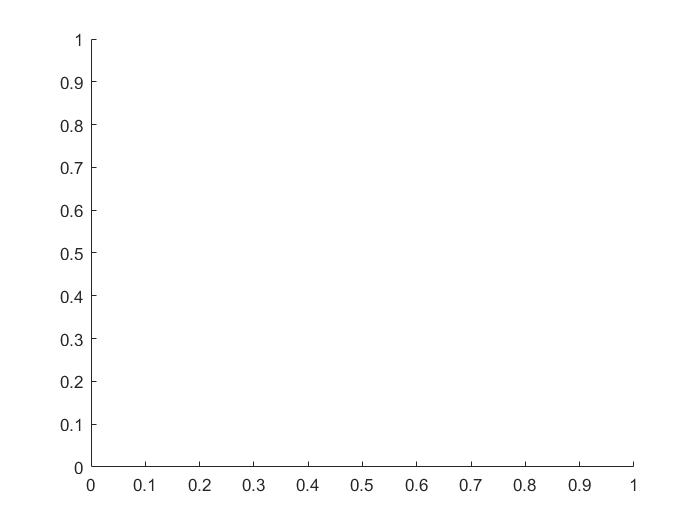

 
 Iteration   Func-count     min f(x)         Procedure
     0            1              -10         


     1            4              -10         initial simplex


     2            6              -30         reflect


     3            7              -30         reflect


     4            8              -30         reflect


     5           10              -30         contract outside


     6           15              -30         shrink


     7           20              -30         shrink


     8           25              -30         shrink


     9           30              -30         shrink


    10           35              -30         shrink


    11           40              -30         shrink


    12           45              -30         shrink


    13           50              -30         shrink


    14           55              -30         shrink


    15           60              -30         shrink


    16           65              -30         shrink


    17           70              -30         shrink


    18           75              -30         shrink


    19           80              -30         shrink


    20           85              -30         shrink


    21           90              -30         shrink


    22           95              -30         shrink


clear
load("ConvolutionArray.mat")
load("tempNeigiamasRodiklisData.mat")
[h1, h2, h3] = runfmincon(allApproximations, convTypes)

plot(h1)
hold on

plot(h2)
yyaxis right
plot(h3)
hold off

function [history_x1, history_x2, history_x3] = runfmincon(allApproximations, convTypes)
    convIndex = ConvolutionEnum.basic;
    approxIndex = ApproximationEnum.mean;
    approximationIndex = (convIndex-1) * uint32(ApproximationEnum.last) + approxIndex;
    
    approx_coef_start = allApproximations(approximationIndex).coeficients;
    
    history_x1 = [];
    history_x2 = [];
    history_x3 = [];
    history_fval = [];
    searchdir = [];
    
    
    % Pass fixed parameters to objfun
    objfun = @(approx_coef_list)objectiveFcn(approx_coef_list,convIndex);
    
    % Set nondefault solver options
    options = optimset("OutputFcn",@outfun,"Display","iter","PlotFcns",...
        "optimplotfval", "MaxIter", 30, "TolX", 1.e-8);
    
    % Solve
    [solution,objectiveValue] = fminsearch(objfun,approx_coef_start,options);
    
    % Clear variables
    clearvars objfun options
    disp(solution)
    disp(objectiveValue)
    
    % Pass fixed parameters to objfun
    objfun = @(approx_coef_list)objectiveFcn(approx_coef_list,convIndex);
    
    % Set nondefault solver options
    options = optimset("OutputFcn",@outfun,"Display","iter","PlotFcns",...
        "optimplotfval", "DiffMaxChange", 0.05);
    
    % Solve
    [solution,objectiveValue] = fminsearch(objfun,approx_coef_start,options);
    
    % Clear variables
    clearvars objfun options
    function f = objectiveFcn(approx_coef_list, convIndex)
        load("ConvolutionArray.mat")
        load("tempNeigiamasRodiklisData.mat")
    
        c1 = approx_coef_list(1);
        c2 = approx_coef_list(2);
        c3 = approx_coef_list(3);
        
        used_approx = ApproximationType("Test", [c1, c2, c3]);
    
        testHitsCorrect = 0;
        testHitsFailed = 0;
        
        %Generate new signal
        minAmplitude = 0.2;
        maxAmplitude = 1.1;
        stepCount = 5;
        data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
        packet_bits = GenerateBits(data_binary);
        singleSigLength = 1040;
        ADCsignalLong = zeros(1, stepCount*singleSigLength);
        idealSignalLong = zeros(1, stepCount*singleSigLength);
        for i = 1:10
            
            for generuojama_amplitude_index = 1:stepCount
                generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
                [idealSignal, ~, ~, ADCsignal, ~] = GenerateSignal(packet_bits, generatedAmplitude);
                copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
                copyIndexLast = singleSigLength*(generuojama_amplitude_index);
                ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
            end
            
            [currentConvolution, ~] = GenerateConvFromType(convTypes(convIndex).diffAmount, ADCsignalLong, ...
                    convTypes(convIndex).convPreambule);
            currentEnergy = GenerateEnergy(ADCsignalLong, length(convTypes(convIndex).convPreambule), -999999999999); %TODO: energy ceiling
            
            %currentApproximation = GenerateApprox(currentEnergy, allApproximations(1));
            currentApproximation = GenerateApprox(currentEnergy, used_approx);
        
            [hitPointsX, hitPointsY] = GenerateHits(currentConvolution, currentApproximation);
            [targetPointsX, targetPointsY] = GenerateTargets(stepCount, convTypes(convIndex).expectedMaximum, length(ADCsignal), currentConvolution);
        
            for ii = 1:length(targetPointsX)
                target_idx = find(hitPointsX == targetPointsX(ii));
                if isempty(target_idx)
                    testHitsFailed = testHitsFailed + 1;
                else
                    testHitsCorrect = testHitsCorrect + 1;
                end
            end
        end
        %testHitsCorrect
        %testHitsFailed
        %plot(currentConvolution)
        %hold on
        %plot(currentApproximation)
        %hold off
        %Find minimum optimisation function
        f = testHitsFailed - testHitsCorrect;
    end

    function stop = outfun(x,optimValues,state)
         stop = false;
     
         switch state
             case 'init'
                 hold on
             case 'iter'
    
                 %x
             % Concatenate current point and objective function
             % value with history. x must be a row vector.
             history_fval = [history_fval, optimValues.fval];
             history_x1 = [history_x1, x(1)];
             history_x2 = [history_x2, x(2)];
             history_x3 = [history_x3, x(3)];
             % Concatenate current search direction with 
             % searchdir.
             %  searchdir = [searchdir;... 
             %               optimValues.searchdirection'];
              % plot(x(1),x(2),'o');
             % Label points with iteration number and add title.
             % Add .15 to x(1) to separate label from plotted 'o'.
              % text(x(1)+.15,x(2),... 
              %      num2str(optimValues.iteration));
              % title('Sequence of Points Computed by fmincon');
    
             case 'done'
                 hold off
             otherwise
         end
    end
end